clc, close all; clear

filename = 'BTC-USD.xlsx';
% closes = readtable(filename)
y = xlsread(filename, 'F:F');
x = [1:length(y)]';
average = sum(y) / length(y);
variance = ((y-average)'*(y-average))/length(y);
fprintf('The mean of the closing values is: %d', average)

The mean of the closing values is: 1.761519e+04

fprintf('The variance of the closing values is: %d', variance)

The variance of the closing values is: 2.792028e+08

X_aug = [x.^5,x.^4,x.^3,x.^2,x,ones(length(x),1)] ;
X_trans = X_aug';
B = ((X_trans*X_aug)^(-1))*X_trans*y;
y_hat = X_aug*B;
x_day = 2236

x_day = 2236

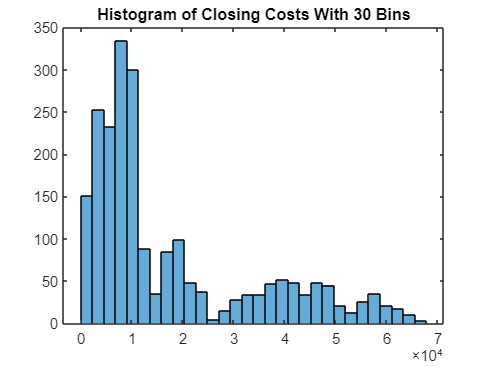

equation_vector = [x_day^5, x_day^4, x_day^3, x_day^2, x_day, 1];
y_hat_prediction = equation_vector*B;
nbins = 30;
histogram(y,nbins); title("Histogram of Closing Costs With 30 Bins")

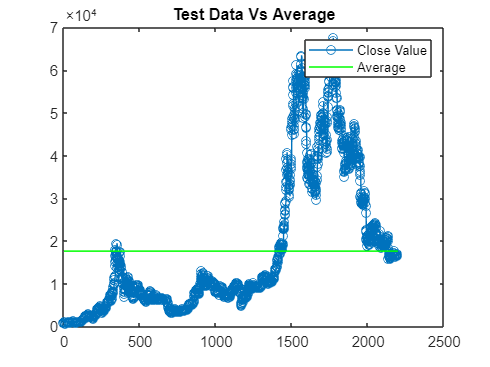


plot(x,y,'-o'); title("Test Data Vs Average");
hold on;
plot(x,average*ones(length(x),1),'g'); 
legend('Close Value','Average')
hold off;


fprintf('Prediction for 1/6/2023 using 5th-degree polynomial is: %d', y_hat_prediction)

Prediction for 1/6/2023 using 5th-degree polynomial is: -1.226829e+04

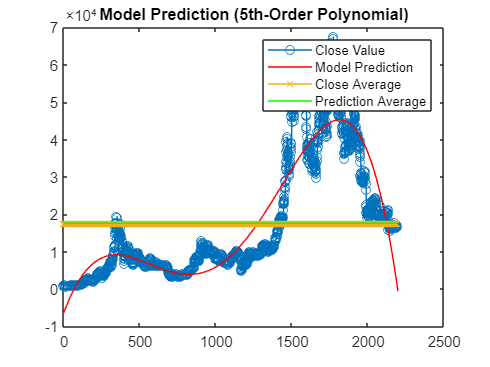

average_prediction = sum(y_hat) / length(y_hat);
plot(x,y,'-o'); title("Model Prediction (5th-Order Polynomial)");
hold on;
plot(x,y_hat,'r'); 
plot(x,average_prediction*ones(length(x),1),'-x'); 
plot(x,average*ones(length(x),1),'g'); 
legend('Close Value','Model Prediction', 'Close Average', 'Prediction Average')
hold off;


% 6th degree for fun

X_aug = [x.^6,x.^5,x.^4,x.^3,x.^2,x,ones(length(x),1)] ;
X_trans = X_aug';
B = ((X_trans*X_aug)^(-1))*X_trans*y;
y_hat = X_aug*B;
equation_vector = [x_day^6,x_day^5, x_day^4, x_day^3, x_day^2, x_day, 1];
y_hat_prediction = equation_vector*B;
fprintf('Prediction for 1/6/2023 using 6th-degree polynomial is: %d', y_hat_prediction)

Prediction for 1/6/2023 using 6th-degree polynomial is: 1.059472e+04

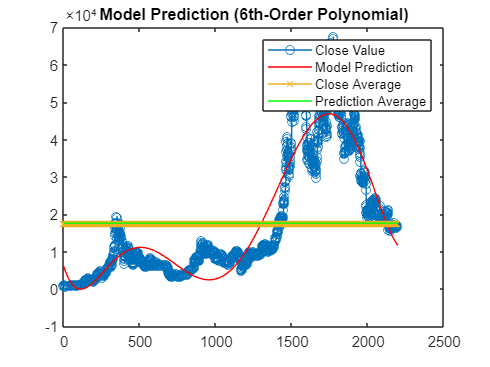


average_prediction = sum(y_hat) / length(y_hat);
plot(x,y,'-o'); title("Model Prediction (6th-Order Polynomial)");
hold on;
plot(x,y_hat,'r'); 
plot(x,average_prediction*ones(length(x),1),'-x'); 
plot(x,average*ones(length(x),1),'g'); 
legend('Close Value','Model Prediction', 'Close Average', 'Prediction Average')
hold off;


% 7th degree for fun
X_aug = [x.^7,x.^6,x.^5,x.^4,x.^3,x.^2,x,ones(length(x),1)] ;
X_trans = X_aug';
B = ((X_trans*X_aug)^(-1))*X_trans*y;
y_hat = X_aug*B;
equation_vector = [x_day^7, x_day^6, x_day^5, x_day^4, x_day^3, x_day^2, x_day, 1];
y_hat_prediction = equation_vector*B;
fprintf('Prediction for 1/6/2023 using 7th-degree polynomial is: %d', y_hat_prediction)

Prediction for 1/6/2023 using 7th-degree polynomial is: 3.271860e+04

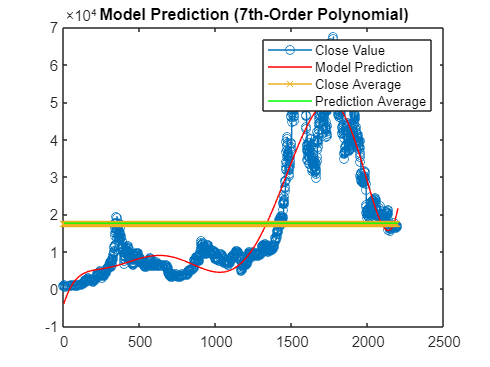


average_prediction = sum(y_hat) / length(y_hat);
plot(x,y,'-o'); title("Model Prediction (7th-Order Polynomial)");
hold on;
plot(x,y_hat,'r'); 
plot(x,average_prediction*ones(length(x),1),'-x'); 
plot(x,average*ones(length(x),1),'g'); 
legend('Close Value','Model Prediction', 'Close Average', 'Prediction Average')
hold off;